## AAE 340 HW11 PROBLEM 3, 4, & 5 MATLAB CODE

clc
close all
clear all

## 4.

## <4a>

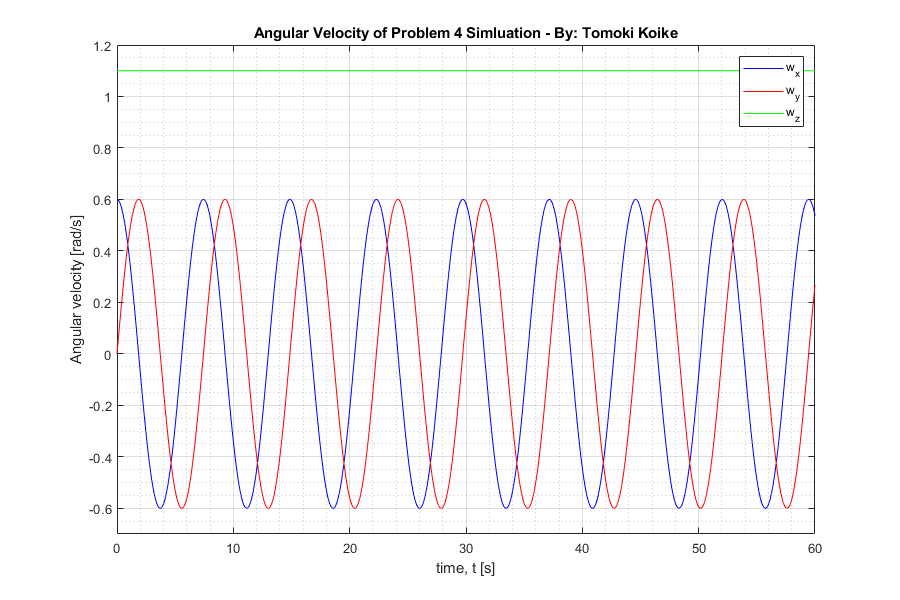

% Assigning the PMOI values [kg-m^2]
Ixx = 2887;
Iyy = 2887;
Izz = 5106;

% Initial values of omega x, y, and z [rad/s]
w0 = [0.6, 0, 1.1];

% ode45 options
options = odeset('RelTol',1e-12, 'AbsTol',1e-12);  % Ode options

% Interval of time
tspan = 0:0.01:60;

% Using ode45
[t, w] = ode45(@(t,w) eulerEOM(t,w,Ixx,Iyy,Izz), tspan, w0, options);

% Extracting results from the ode45 result
w_x = w(:,1);  % Omega x
w_y = w(:,2);  % Omega y
w_z = w(:,3);  % Omega z

% Plotting
figure('Renderer','painters', "Position",[10 10 900 600])
plot(t, w_x, '-b', t, w_y, '-r', t, w_z, '-g')
title({'Angular Velocity of Problem 4 Simluation - By: Tomoki Koike'})
xlabel('time, t [s]')
ylabel('Angular velocity [rad/s]')
grid on
grid minor
box on
ylim([-0.7 1.2])
legend('w_x', 'w_y', 'w_z')

## <4b>

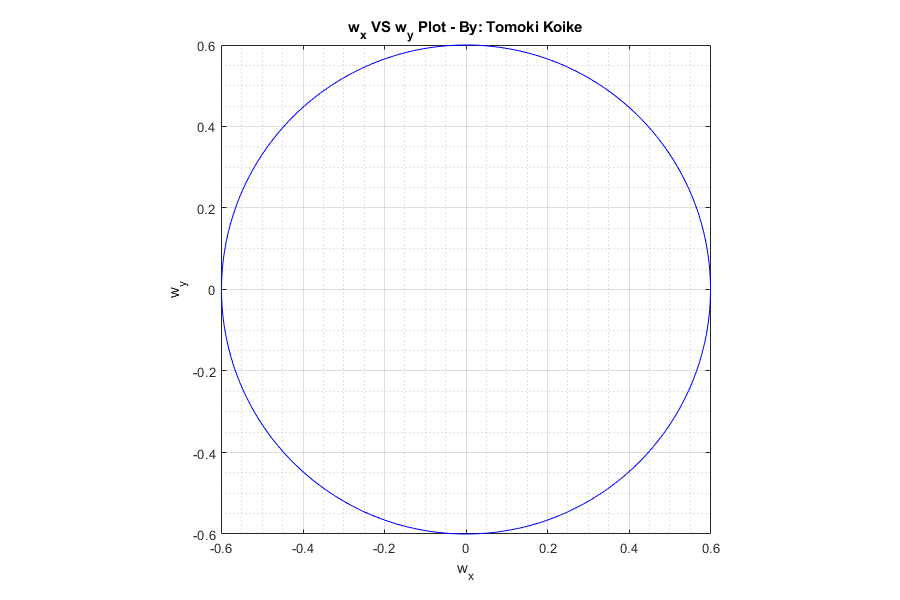

% Plotting
figure('Renderer','painters', "Position",[10 10 900 600])
plot(w_x, w_y, '-b')
title({'w_x VS w_y Plot - By: Tomoki Koike'})
xlabel('w_x')
ylabel('w_y')
grid on
grid minor
box on
axis square

## <4c>

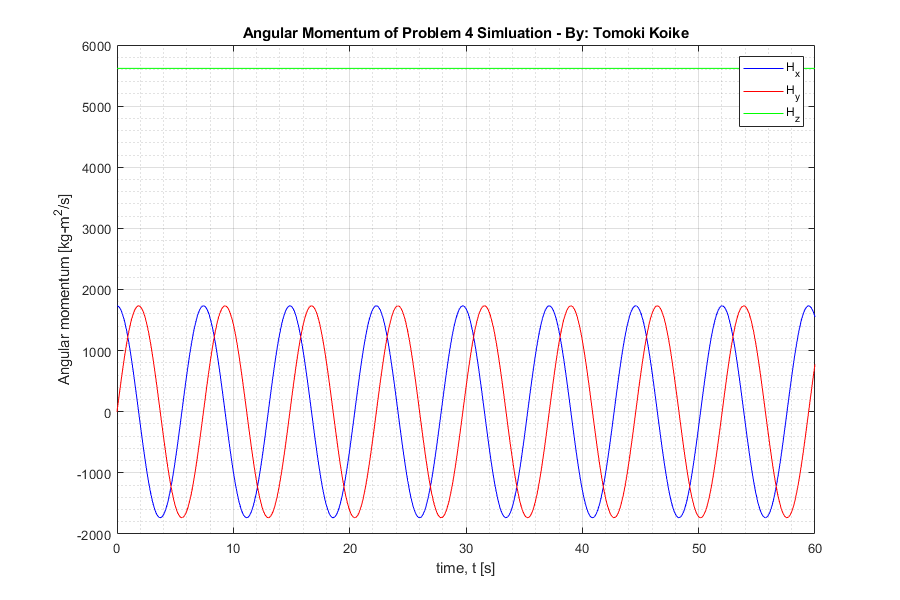

% Getting the angular momentum
H = angMmt(Ixx, Iyy, Izz, w_x, w_y, w_z);

% Extracting values
Hx = H(:,1); 
Hy = H(:,2);
Hz = H(:,3);

% Plotting
figure('Renderer','painters', "Position",[10 10 900 600])
plot(t, Hx, '-b', t, Hy, '-r', t, Hz, '-g')
title({'Angular Momentum of Problem 4 Simluation - By: Tomoki Koike'})
xlabel('time, t [s]')
ylabel('Angular momentum [kg-m^2/s]')
grid on
grid minor
box on
legend('H_x', 'H_y', 'H_z')

## <4d>

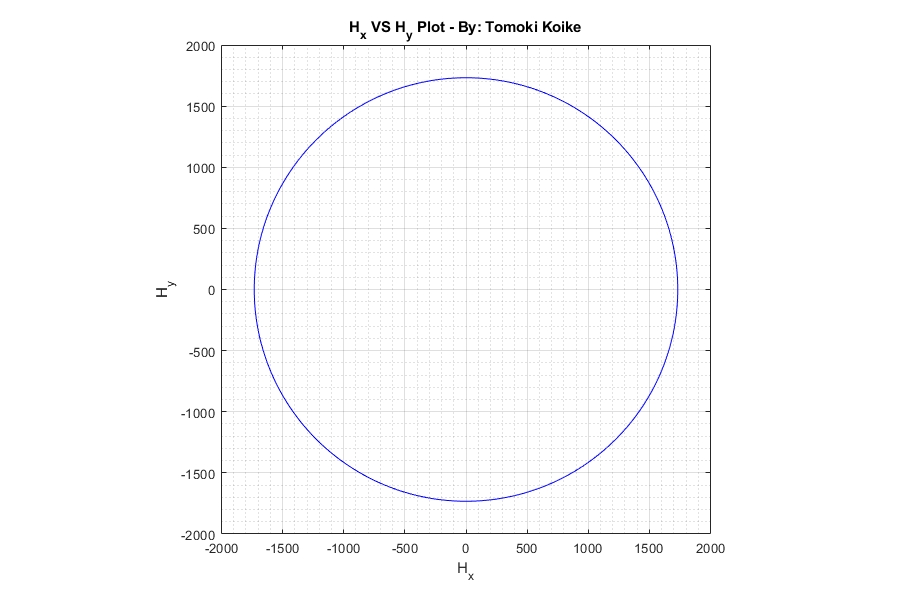

% Plotting
figure('Renderer','painters', "Position",[10 10 900 600])
plot(Hx, Hy, '-b')
title({'H_x VS H_y Plot - By: Tomoki Koike'})
xlabel('H_x')
ylabel('H_y')
grid on
grid minor
box on
axis square

## <4e>

wx_max = max(w_x);
disp(wx_max);

    0.6000



Hx_max = max(Hx);
disp(Hx_max);

   1.7322e+03



disp(max(Hz));

   5.6166e+03



## 5.

## <5a>

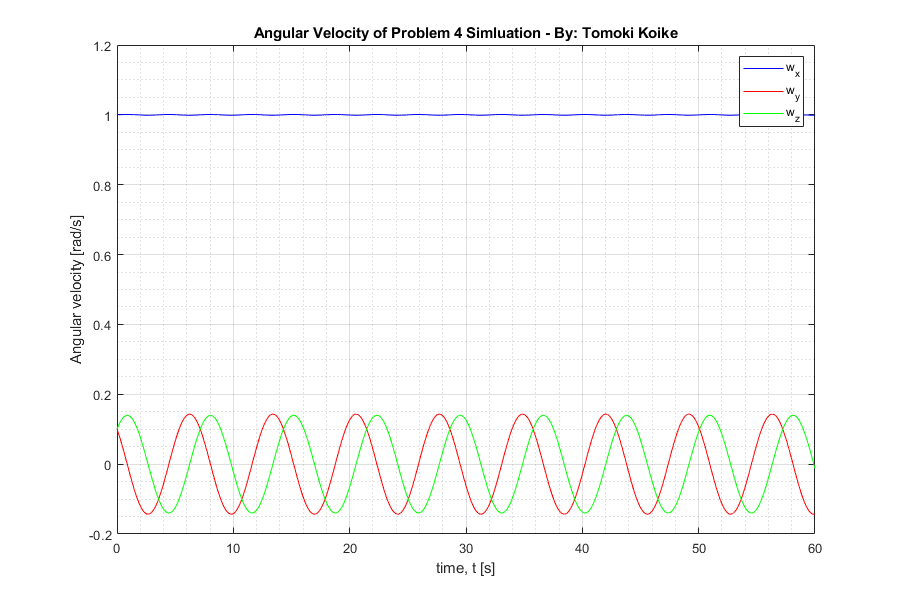

% Assigning the PMOI values [kg-m^2]
Ixx = 0.0080;
Iyy = 0.0050;
Izz = 0.0035;

% Initial values of omega x, y, and z [rad/s]
w0 = [1, 0.1, 0.1];

% Using ode45
[t, w] = ode45(@(t,w) eulerEOM(t,w,Ixx,Iyy,Izz), tspan, w0, options);

% Extracting results from the ode45 result
w_x = w(:,1);  % Omega x
w_y = w(:,2);  % Omega y
w_z = w(:,3);  % Omega z

% Plotting
figure('Renderer','painters', "Position",[10 10 900 600])
plot(t, w_x, '-b', t, w_y, '-r', t, w_z, '-g')
title({'Angular Velocity of Problem 4 Simluation - By: Tomoki Koike'})
xlabel('time, t [s]')
ylabel('Angular velocity [rad/s]')
grid on
grid minor
box on
legend('w_x', 'w_y', 'w_z')

## <5b>

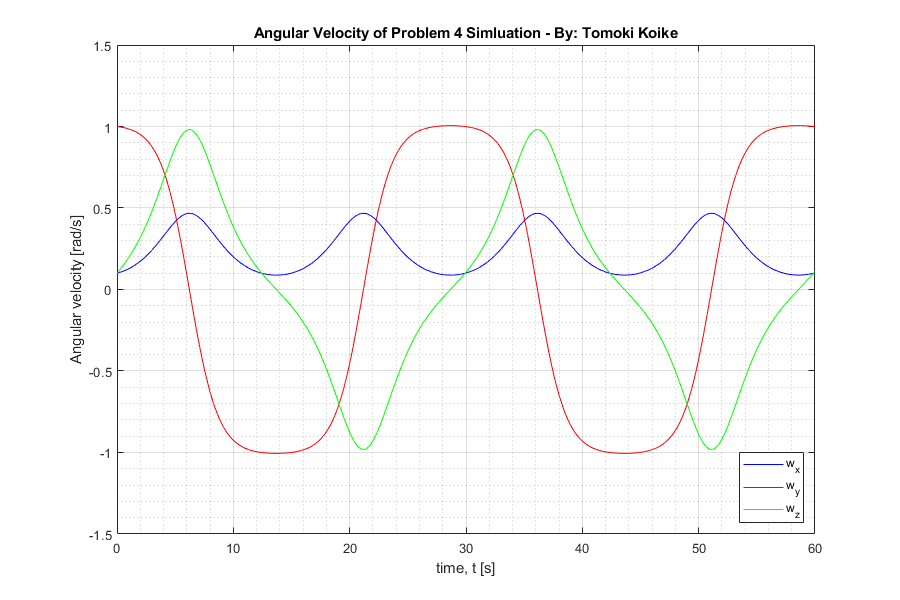

% Initial values of omega x, y, and z [rad/s]
w0 = [0.1, 1, 0.1];

% Using ode45
[t, w] = ode45(@(t,w) eulerEOM(t,w,Ixx,Iyy,Izz), tspan, w0, options);

% Extracting results from the ode45 result
w_x = w(:,1);  % Omega x
w_y = w(:,2);  % Omega y
w_z = w(:,3);  % Omega z

% Plotting
figure('Renderer','painters', "Position",[10 10 900 600])
plot(t, w_x, '-b', t, w_y, '-r', t, w_z, '-g')
title({'Angular Velocity of Problem 4 Simluation - By: Tomoki Koike'})
xlabel('time, t [s]')
ylabel('Angular velocity [rad/s]')
grid on
grid minor
box on
legend('w_x', 'w_y', 'w_z', 'Location', 'southeast')

## <5c>

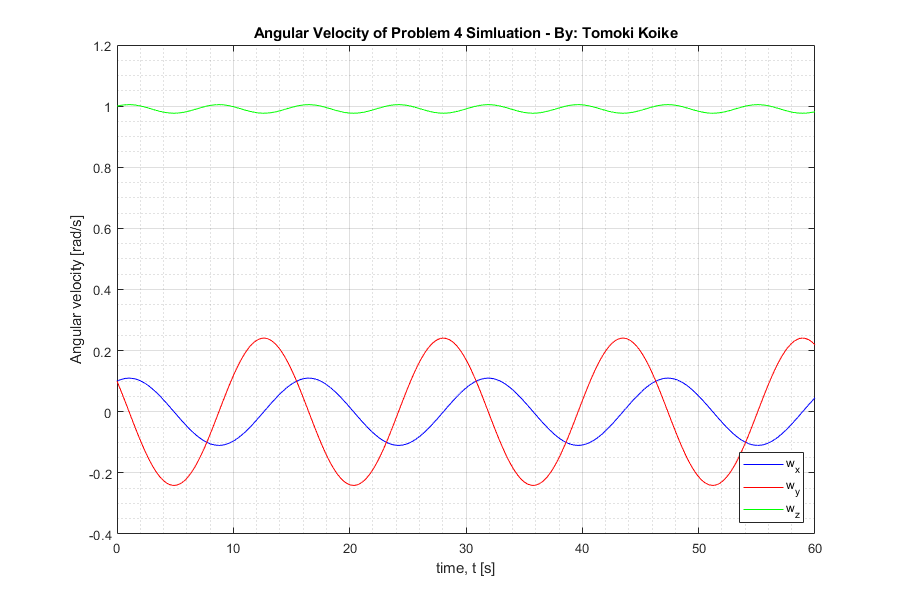

% Initial values of omega x, y, and z [rad/s]
w0 = [0.1, 0.1, 1];

% Using ode45
[t, w] = ode45(@(t,w) eulerEOM(t,w,Ixx,Iyy,Izz), tspan, w0, options);

% Extracting results from the ode45 result
w_x = w(:,1);  % Omega x
w_y = w(:,2);  % Omega y
w_z = w(:,3);  % Omega z

% Plotting
figure('Renderer','painters', "Position",[10 10 900 600])
plot(t, w_x, '-b', t, w_y, '-r', t, w_z, '-g')
title({'Angular Velocity of Problem 4 Simluation - By: Tomoki Koike'})
xlabel('time, t [s]')
ylabel('Angular velocity [rad/s]')
grid on
grid minor
box on
legend('w_x', 'w_y', 'w_z', 'Location', 'southeast')

### FUNCTIONS

function dwdt = eulerEOM(t, w, Ixx, Iyy, Izz)
    % Function of Euler's equation of motion for ode45
    % If there are no external forces
    Mx = 0;
    My = 0;
    Mz = 0;
    
    % The state variable function
    dwdt(1) = Mx/Ixx - (Izz - Iyy)*w(2)*w(3)/Ixx;
    dwdt(2) = My/Iyy - (Ixx - Izz)*w(1)*w(3)/Iyy;
    dwdt(3) = Mz/Izz - (Iyy - Ixx)*w(1)*w(2)/Izz;
    
    dwdt = dwdt';
end

function H = angMmt(Ixx, Iyy, Izz, w_x, w_y, w_z)
    % Function to calculate angular momentum 
    Hx = Ixx*w_x;
    Hy = Iyy*w_y;
    Hz = Izz*w_z;
    H = [Hx, Hy, Hz];
end